# 運転データから車両をモデリング

## 運転データを作成

Manual_Trajectory_Generator.slxが開いたら実行し、舵角を調整して運転データを作成する。

上向きのみに移動するようにする。下向きに移動しないようにする。

model_name = 'Manual_Trajectory_Generator';
open_system(model_name);
%warning('off', 'all')

## 運転データから車両の状態空間モデルを作成

% 車両の履歴データと入力（操舵角）データを用いて車両の横方向のプラントモデルを同定
% 1100個のデータを3ずつに分けて、366個のデータセットを作る。
% そのデータをmergeして366個の実験を含む時間領域データセットを作る。
result = out;
result_data = getElement(result.logsout, 'y').Values;

ts = get_TimeStep('sim_data_vehicle.sldd');

% 状態
px_result = result_data.px.Data;
py_result = result_data.py.Data;
theta_result = result_data.theta.Data;
r_result = result_data.r.Data;
beta_result = result_data.beta.Data;
V_result = result_data.V.Data;

% 入力δ
delta = result_data.delta.Data;


result_mat = [px_result, py_result, theta_result, r_result, beta_result, V_result];

% データセット初期化
data_set_list = {};

% いくつのデータを1セットとするか(奇数のみ)
data_num = 5;

% データセット作成
i0 = 1;

for i = 1:length(delta)/data_num - 1
    % 座標変換するウェイポイント
    ref_point = i0 + (i-1) * data_num;

    % ref_point-1 , ref_point, ref_point+1のデータを一つのデータセットとする。
    % 初期化
    state_data = zeros(data_num,6);
    % 座標変換するウェイポイントの状態
    referenceState = result_mat(ref_point, :);

    %一つのデータセットの中に入れる状態を変換して格納
    for j = 1:data_num
        state = result_mat(ref_point + j - i0, :);
        state_data(j,:) = transformState(referenceState, state).';
    end

    %データセットに対応するδを格納
    delta_data = delta(ref_point : ref_point + data_num - 1);
    % iddata型に変換
    data_set_list{i} = iddata(state_data(:,2:4), delta_data, ts);
end

% データセットをマージ
data_set = merge(data_set_list{:});

na = [[1, 1, 1];
      [1, 1, 1];
      [1, 1, 1]];
nb = [1;1;1];
nk = [1;1;1];
sys_arx = arx(data_set, [na nb nk]);
sys_ss = ss(sys_arx);

## 等価二輪モデルを用いた状態空間モデルと比較

等価二輪モデルを用いた状態空間モデルの作成

%線形lmpcObj1を作成

% パラメータ

x0 = [0; 0; 0; 0; 0; 10];
%u0 = zeros(size(U, 1), 1);

%uNum_MPC = size(u0, 1);
%xNum_MPC = size(x0, 1);
%yNum_MPC = size(Y, 1);
yNum_MPC = 6;


% 質量
m_val = 2000;
% 車両重心から前後輪までの長さ
l_f_val = 1.4;
l_r_val = 1.6;
% ヨー極慣性
I_val = 4000;
%等価コーナリングパワー
K_f_val = 12e3;
K_r_val = 11e3;
div_min = 1e-3;



xl0 = [0; 0];
ul0 = 0;
mdl0 = 0;

V_const = 3;

Ald = [1, V_const*ts;
        0, 1];
Bld = [0, 0;
       V_const/(l_f_val + l_r_val)*ts, -1*ts];
Cld = [1, 0;
       0, 1];
Dld = [0, 0; 
       0, 0];
dlsys1 = ss(Ald, Bld, Cld, Dld, ts);

l_normal_input_names = {'delta', 'md'};
l_state_names = {'py', 'theta'};
l_output_names = {'py', 'theta'};
dlsys1.InputName = l_normal_input_names;
dlsys1.StateName = l_state_names;
dlsys1.OutputName = l_output_names;
dlsys1.InputDelay = 2;
dlsys1 = setmpcsignals(dlsys1,'MV', 1,'MD',2);
dlsys1

dlsys1 =
 
  A = 
             py  theta
   py         1    0.3
   theta      0      1
 
  B = 
          delta     md
   py         0      0
   theta    0.1   -0.1
 
  C = 
             py  theta
   py         1      0
   theta      0      1
 
  D = 
          delta     md
   py         0      0
   theta      0      0
 
  入力遅延 (サンプル期間): 2  2 
 
入力グループ:                
        名前         チャネル
    Manipulated     1  
     Measured       2  
                       
出力グループ:             
       名前       チャネル
    Measured    1,2 
                    
サンプル時間:  0.1 seconds
離散時間状態空間モデル。



等価二輪モデルを用いた状態空間モデルとデータから導出した状態空間モデルの比較

% 実際のシミュレーション結果との誤差を計算
rms1 = 0;
rms2 = 0;

start = 10;
step = 10;
%i = 10;
for i = start:(start + step - 1)
    
    % シミュレーションの時間ベクトルを作成
    t = (0:ts:(length(data_set_list{i}.u)-1)*ts).';
    
    % 教科書の線形近似モデル
    %dlsys1
    simOut1 = lsim(dlsys1, [data_set_list{i}.u, data_set_list{i}.y(:,3)], t, data_set_list{i}.y(1,1:2));
    
    % 同定したモデルを使ってシミュレーション
    %sys_ss
    simOut2 = lsim(sys_ss, data_set_list{i}.u, t, data_set_list{i}.y(1,:));
    
    % simulinkの車両モデルから得られた実際のシミュレーション結果
    real_data = data_set_list{i}.y;
    
    % 同定したモデル 0.1以下
    rms1 = rms1 + rms(simOut1 - real_data(:,1:2))/step;
    rms2 = rms2 + rms(simOut2 - real_data)/step;


end
disp(rms1)

    0.0113    0.0067



disp(rms2)

    0.0002    0.0001    0.0012



## 目標軌道を設定

model_name = 'Manual_Trajectory_Generator';
open_system(model_name);

目標軌道データを整理

% Manual_trajectory_Generatorを動かす。
ref_data = getElement(out.logsout, 'y').Values;

px_ref = ref_data.px.Data;
py_ref = ref_data.py.Data;
theta_ref = ref_data.theta.Data;
r_ref = ref_data.r.Data;
beta_ref = ref_data.beta.Data;
V_ref = ref_data.V.Data;

% 距離データを追加する。
dist_ref = cumsum(sqrt(diff(px_ref).^2 + diff(py_ref).^2));
dist_ref = dist_ref - dist_ref(1);

## 等価二輪モデルを用いたMPCとデータから導出されたMPCを比較

等価二輪モデル

lmpcObj1 = mpc(dlsys1);

-->"PredictionHorizon" プロパティが空です。既定の 10 を仮定します。
-->"ControlHorizon" プロパティが空です。既定の 2 を仮定します。
-->"Weights.ManipulatedVariables" プロパティが空です。既定の 0.00000 を仮定します。
-->"Weights.ManipulatedVariablesRate" プロパティが空です。既定の 0.10000 を仮定します。
-->"Weights.OutputVariables" プロパティが空です。既定の 1.00000 を仮定します。
   for output(s) y1 and zero weight for output(s) y2 


% 予測ホライズン、制御ホライズンの設定
horizon = 16;
horizon_index = 1:horizon;
lmpcObj1.PredictionHorizon = horizon; % 50
lmpcObj1.ControlHorizon = horizon;
Xdl = xl0;
Udl = ul0;
Ydl = Cld * xl0;
DXdl = Ald * xl0 + Bld * [ul0; mdl0] - xl0;
% ノミナル状態を更新
lmpcObj1.Model.Nominal = struct('U',Udl,'Y',Ydl,'X',Xdl,'DX',DXdl);
% 制約
% 操舵角は30deg以内であること
delta_limit = 30;
lmpcObj1.ManipulatedVariables(1).Max = delta_limit * pi / 180;
lmpcObj1.ManipulatedVariables(1).Min = -delta_limit * pi / 180;
% 加速度は2m/s^2以内であること


% 最適化の重みを設定
lmpcObj1.Weights.OutputVariables = [repmat([0.1, 0.0], horizon-1, 1);
                                  [1, 0]];
lmpcObj1.Weights.ManipulatedVariables = 0.1;

lmpcObj = lmpcObj1;

model_name = 'Vehicle_system_Adaptive_MPC';
result_l1 = sim(model_name);

-->遅延を状態に変換します。
   測定出力チャネル #1 に外乱が追加されていないと仮定します。
-->測定出力チャネル #2 に追加された出力外乱は、合成ホワイト ノイズであると仮定します。
-->"Model.Noise" プロパティが空です。それぞれの測定出力にホワイト ノイズを仮定します。


## データ

Ald2 = sys_ss.A(1:2,1:2);
Bld2 = [sys_ss.B(1:2),sys_ss.A(1:2,3)];
Cld2 = sys_ss.C(1:2,1:2);
Dld2 = [sys_ss.D(1:2),sys_ss.C(1:2,3)];

%線形MPC1
xl0 = [0; 0];
ul0 = 0;
mdl0 = 0;

dlsys2 = ss(Ald2, Bld2, Cld2, Dld2, ts);

l_normal_input_names = {'delta', 'md'};
l_state_names = {'py', 'theta'};
l_output_names = {'py', 'theta'};
dlsys2.InputName = l_normal_input_names;
dlsys2.StateName = l_state_names;
dlsys2.OutputName = l_output_names;

dlsys2 = setmpcsignals(dlsys2,'MV', 1,'MD',2);
lmpcObj2 = mpc(dlsys2);

-->"PredictionHorizon" プロパティが空です。既定の 10 を仮定します。
-->"ControlHorizon" プロパティが空です。既定の 2 を仮定します。
-->"Weights.ManipulatedVariables" プロパティが空です。既定の 0.00000 を仮定します。
-->"Weights.ManipulatedVariablesRate" プロパティが空です。既定の 0.10000 を仮定します。
-->"Weights.OutputVariables" プロパティが空です。既定の 1.00000 を仮定します。
   for output(s) y1 and zero weight for output(s) y2 


-->測定出力チャネル #1 に追加された出力外乱は、合成ホワイト ノイズであると仮定します。
-->測定出力チャネル #2 に追加された出力外乱は、合成ホワイト ノイズであると仮定します。
-->"Model.Noise" プロパティが空です。それぞれの測定出力にホワイト ノイズを仮定します。


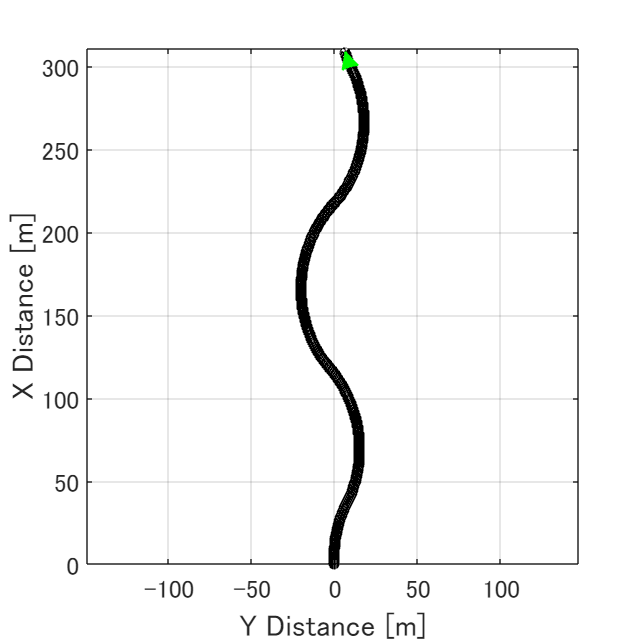

horizon = 16;
horizon_index = 1:horizon;
lmpcObj2.PredictionHorizon = horizon; % 50
lmpcObj2.ControlHorizon = horizon;
Udl = ul0;
Ydl = Cld * xl0;
Xdl = xl0;
DXdl = Ald * xl0 + Bld * [ul0; mdl0] - xl0;
% ノミナル状態を更新
lmpcObj2.Model.Nominal = struct('U',Udl,'Y',Ydl,'X',Xdl,'DX',DXdl);
% 制約
% 操舵角は30deg以内であること
lmpcObj2.ManipulatedVariables(1).Max = delta_limit * pi / 180;
lmpcObj2.ManipulatedVariables(1).Min = -delta_limit * pi / 180;
% 加速度は2m/s^2以内であること


% 最適化の重みを設定
lmpcObj2.Weights.OutputVariables = [repmat([0.1, 0.0], horizon-1, 1);
                                  [1, 0]];
lmpcObj2.Weights.ManipulatedVariables = 0.1;

lmpcObj = lmpcObj2;
result_l2 = sim(model_name);

## 図示

rmse
    0.1592



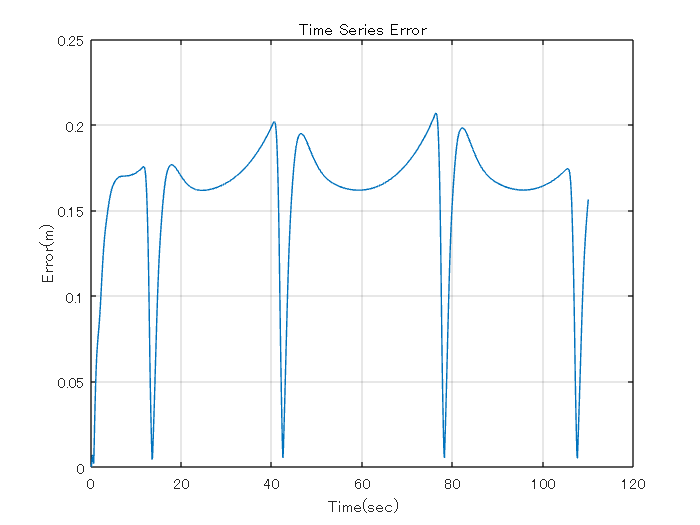

figure_error(result_l1, ts)

rmse
    0.1404



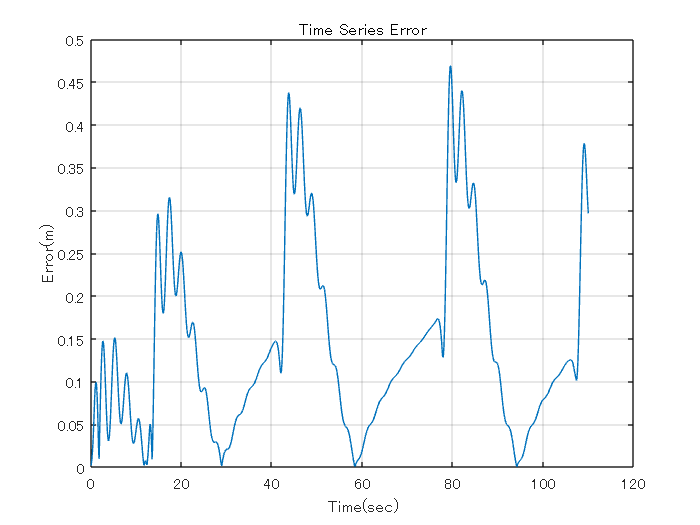

figure_error(result_l2, ts)